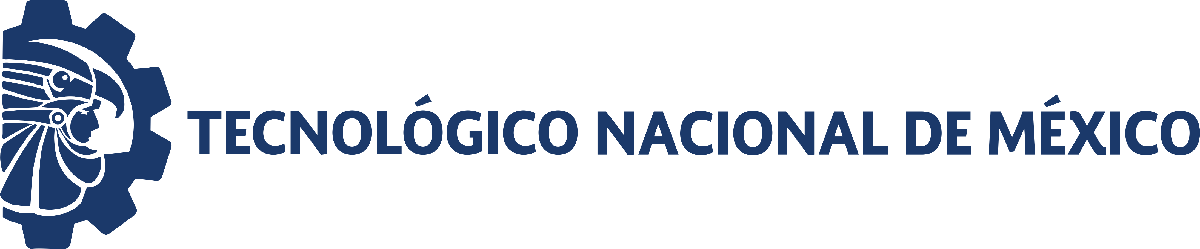                                 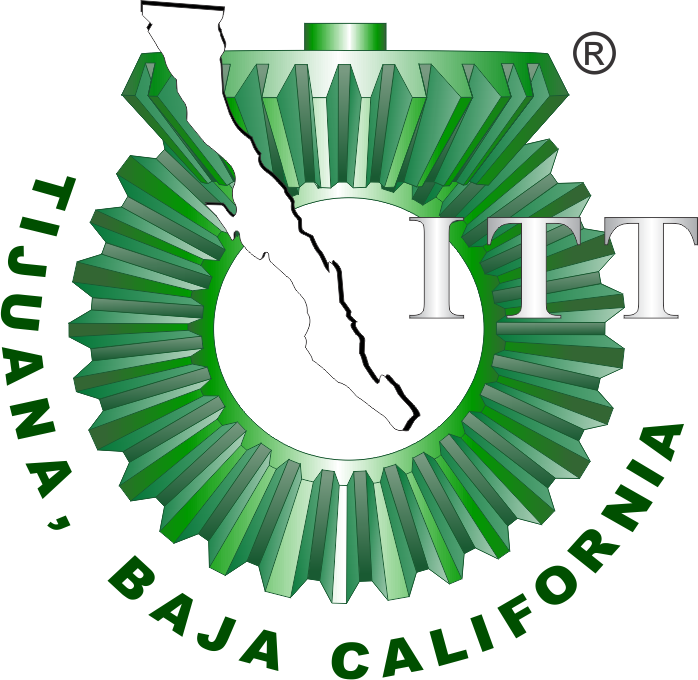

# Práctica tres: Modelado y control del sistema musculoesqueletico 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

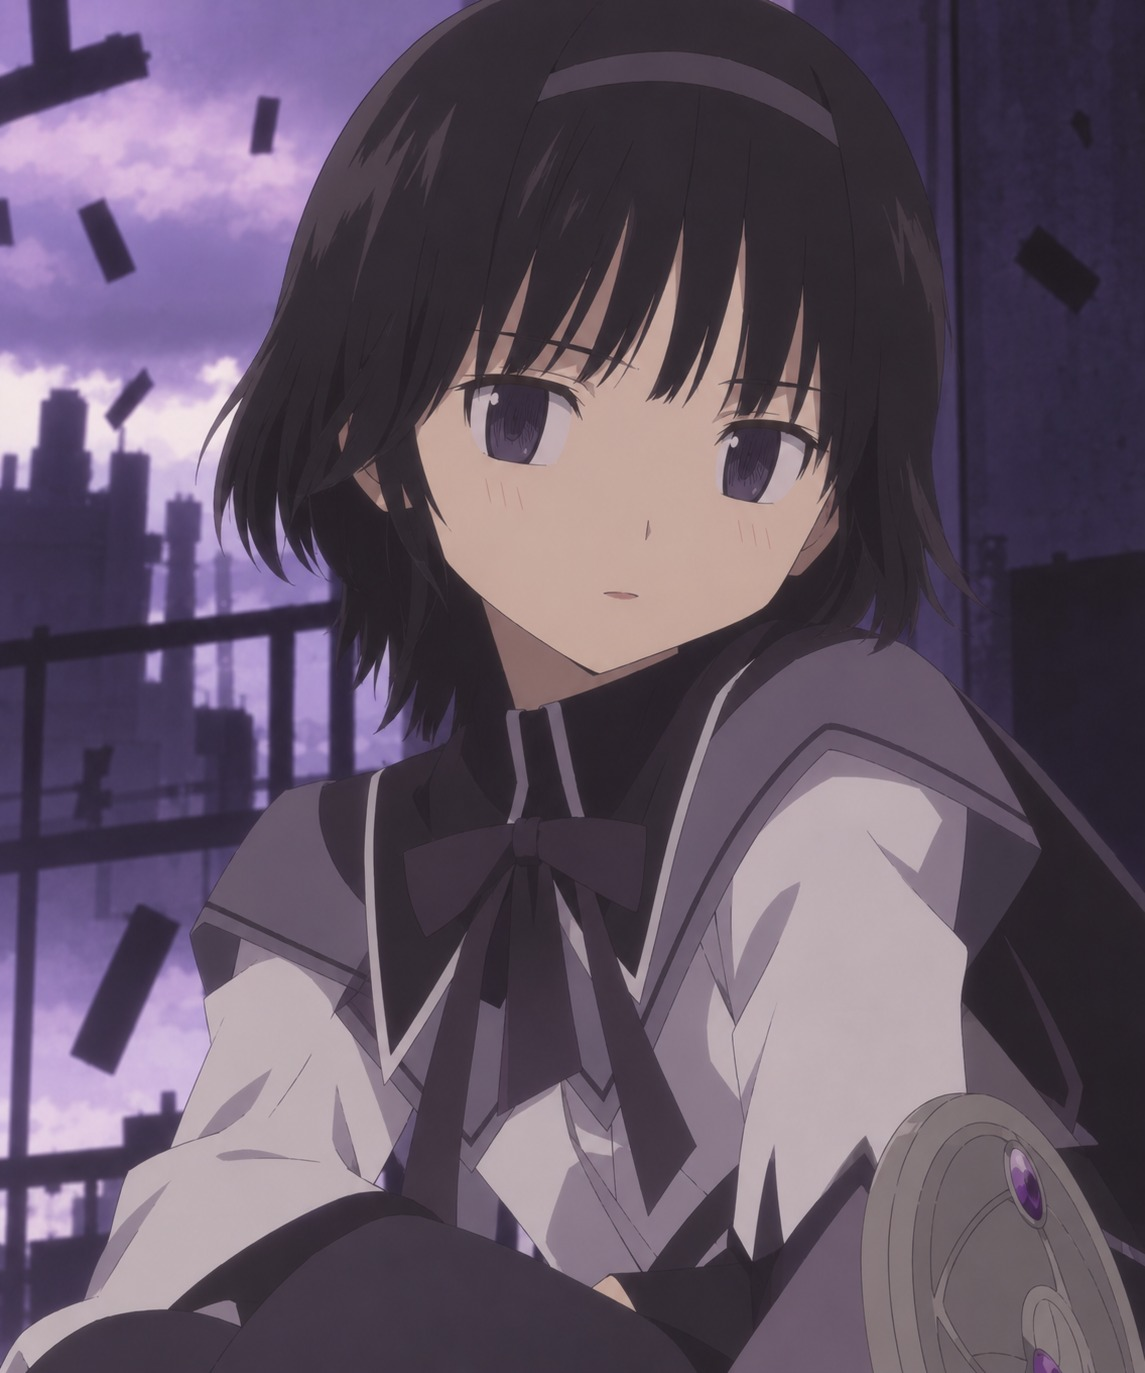

Nombre del alumno: Carolina Gamez Flores

Número de control: 23212193

Correo institucional: l23212193**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('sistema',parameters);

% set_param('sistema/Vs(t)','VectorFormat','1-D array')

## Respuesta: Control y caso

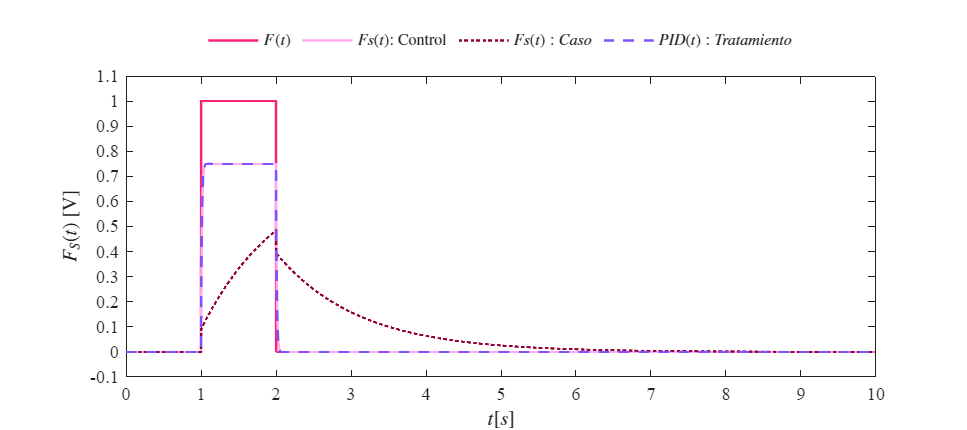

plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,'Caso');

## **Función: Respuestas de la simulación**

function plotsignals(t,F,Fsx,Fsy,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [1,1,18,8])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [246, 36, 119]/255;  
    clr2 = [255, 173, 238]/255;   
    clr3 = [146, 0, 58]/255;   
    clr4 = [128, 81, 255]/255;
    order = [clr1; clr2; clr3; clr4]; colororder(order)

    plot(t,F,'-',t,Fsx,'-',t,Fsy,':',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));

    L = legend('$F(t)$','$Fs(t)$: Control','$Fs(t): Caso$','$PID(t): Tratamiento$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal', 'Box', 'off', 'NumColumns', 4)
  
    xlabel('$ t[s]$','Interpreter','latex')
    ylabel('$F_S(t)$ [V]', 'Interpreter','latex')

    xlim([0 10]); xticks(0:1:10)

    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    exportgraphics(gcf, [signal,'_matlab.pdf'], 'ContentType', 'vector')
  
end